# Rotate some media pipe data!

**2022/04/22 - trentondwirth at gmail dot com**

### **The way that this script works is takes your "favorite frame" where the feet are flat on the ground, and then uses that body position to execute some rotations and translations so that the data is standing on the XY plane, and the body is in the positive Z direction**

### **Depending on the vectors you make out of the feet that will make up your desired ground plane(e.g., left_heel -> left_toe, left_heel ->right_heel) the data might come out upsidedown. I haven't built a mechanism to deal with that yet, but this code is a WIP and we'll fix these things in the :sparkles: future :sparkles: **

#### Clean up your environment

close all
clearvars
restoredefaultpath

#### Get your basic paths right

homePath = 'your path here'; % this is the directory path that this file is siting in
dataPath = [dataPath '/data']; 
toolboxPath = [dataPath '/toolbox']; % where to find the toolboxes this code uses
npyReaderPath = [dataPath '/toolbox/npy-matlab']; % path to the npy reader tools

addpath(genpath(homePath));
addpath(genpath(dataPath));
addpath(genpath(toolboxPath));
addpath(genpath(npyReaderPath));

## "origin correcting" real data

npy_data = readNPY('mediaPipeSkel_3d_smoothed.npy'); % use the readNPY function https://travis-ci.org/github/kwikteam/npy-matlab

num_markers = size(npy_data,2); % get total number of "markers" or "joint" positions

left_heel = 30; % I went through the trouble of finding and hard coding the positions on the feet, if I remember I'll throw a picture in the README
left_toe = 32;

right_heel = 31;
right_toe = 33;

#### Your `favorite_frame` is really important here: you want to find a frame where the feet are flat on the ground. I recommend using the debug plot below to sift through your data to find something that looks good.

tip: you can make this process go faster by looking at the video output of the freemocap pipeline

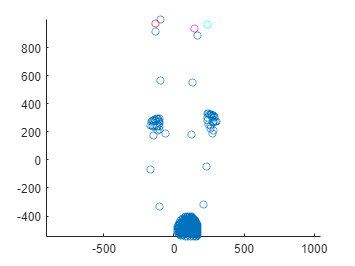

debug = 1; % set to 1 if you want debug plots -- this happens all throughout the .mlx script, sometimes you'll want them and sometimes you wont

favorite_frame = 100; % arbitrarily chose 100 to start with

if debug == 1

    % remember, this test plot is the unrotated data, so it wont look good
    % yet!

    testData = squeeze(npy_data(favorite_frame,:,:));
    
    figure(randi(200000));
    hold on;
    scatter3(testData(:,1),testData(:,2),testData(:,3));
    scatter3(testData(right_heel,1),testData(right_heel,2),testData(right_heel,3),'r');
    scatter3(testData(right_toe,1),testData(right_toe,2),testData(right_toe,3),'g');
    scatter3(testData(left_heel,1),testData(left_heel,2),testData(left_heel,3),'m');
    scatter3(testData(left_toe,1),testData(left_toe,2),testData(left_toe,3),'c');
    axis equal
    hold off;


end


Once you've found your favorite frame, start doing vector-y things

% grab "markers" on the feet
p = squeeze(npy_data(favorite_frame,left_heel,:))';
q = squeeze(npy_data(favorite_frame,right_heel,:))'; 
r = squeeze(npy_data(favorite_frame,left_toe,:))'; 

% set up an empty array to make this process go a little faster
origin_corrected_3D_data = nan(size(npy_data,1),size(npy_data,2),size(npy_data,3));

% for each marker, rotate its entire time series
for iMarkers = 1:num_markers

    this_marker_data_t_xyz = squeeze(npy_data(:,iMarkers,:));
    
    %                custom function with nested dependencies that I made.
    %                If you want a refresher on linear algebra, 
    %                check out the 3Blue1Brown tutorial on youtube, it's great
    %       https://www.youtube.com/playlist?list=PLZHQObOWTQDPD3MizzM2xVFitgF8hE_ab

    output_3D_data = translation_and_rotation_to_origin(p,q,r,this_marker_data_t_xyz,0); % the last value here is for debug plots, this should only be used with nested breakpoints

    origin_corrected_3D_data(:,iMarkers,:) = output_3D_data;

end

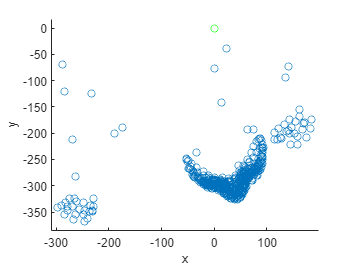

debug = 1;
% this is another test plot plot of your origin corrected 3D data!

resultData = squeeze(origin_corrected_3D_data(favorite_frame,:,:));

figure(randi(200000));
hold on;
scatter3(resultData(:,1),resultData(:,2),resultData(:,3));
plot3(0,0,0,'go')
xlabel 'x'
ylabel 'y'
zlabel 'z'
axis equal
hold off;



% take the right heel to right toe vector, and the y-normal to calculate
% the angular difference between the right foot and the y-axis at our
% favorit frame. Then, rotate the data along the z-axis by that angular
% difference

right_foot_vect = squeeze(origin_corrected_3D_data(favorite_frame,right_toe,:)-origin_corrected_3D_data(favorite_frame,right_heel,:));
left_foot_vect = squeeze(origin_corrected_3D_data(favorite_frame,left_toe,:)-origin_corrected_3D_data(favorite_frame,left_heel,:));
heel_vect_LR = squeeze(origin_corrected_3D_data(favorite_frame,right_heel,:)-origin_corrected_3D_data(favorite_frame,left_heel,:));

x_norm_vect = [1;0;0];
y_norm_vect = [0;1;0];

% the rotation angle needed to align the toe with the y-axis
rot_angle_y = atan2d(norm(cross(left_foot_vect,y_norm_vect)), dot(left_foot_vect,y_norm_vect));

% rotation angle (degrees) between the x-axis and the right heel
rot_angle_x = atan2d(norm(cross(heel_vect_LR,x_norm_vect)), dot(heel_vect_LR,x_norm_vect));
 
  

The code below simply rotates the data so that the participant is "facing forward", or in this case, positive Y

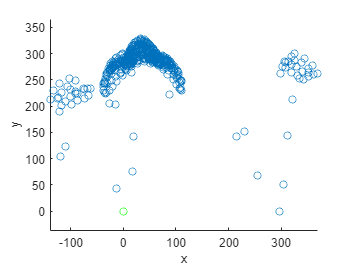

% set up empty array for speed
origin_corrected_3D_data_rotated = nan(size(npy_data,1),size(npy_data,2),size(npy_data,3));

% translate the data to polar coordinates and apply a rotation

for iiMarkers = 1:num_markers

    this_markerii_data_t_xyz = squeeze(origin_corrected_3D_data(:,iiMarkers,:));

    % using the rot_angle_x to align the heels with the x-axis; I think
    % this looks better than aligning the left toe with the y axis
    this_marker_data_t_xyz_rotated = rotate_using_polar_coordinates(this_markerii_data_t_xyz,rot_angle_x);

    origin_corrected_3D_data_rotated(:,iiMarkers,:) = this_marker_data_t_xyz_rotated;

end

debug = 1;

if debug == 1

    resultData_rot = squeeze(origin_corrected_3D_data_rotated(favorite_frame,:,:));
    
    figure(randi(200000));
    hold on;
    scatter3(resultData_rot(:,1),resultData_rot(:,2),resultData_rot(:,3));
    plot3(0,0,0,'go')
    xlabel 'x'
    ylabel 'y'
    zlabel 'z'
    axis equal
    hold off;


end

#### save out a mat file and an npy file of the work you've done!

clearvars -except origin_corrected_3D_data_rotated
save origin_corrected_and_rotated_mediapipe_smoothed_2022-03-30
writeNPY(origin_corrected_3D_data_rotated, 'mediapipe_origin_corrected_and_rotated.npy');